    storage part

% clear;

s = 7; %total # of nodes
x = 1; %# of r_i
y = 1; %# of c_i
z = 1; %# of c_{i+1}
% lambda = 2453.7*2/s/(s-1);

mobi = 'hete39-';
Lambda = 400;    
% tempRatio = 1;
smplIntrv = 60;
r_l = 6000;
cs = 5;

lambda = getLambda(['C:\Users\jzyan\OneDrive\PhDwork\opnet\data\mar2019\lambda\n' num2str(s) '-' mobi 'con-cs' num2str(cs) '-pit6k-cl6k-rr' num2str(Lambda) '-'], s);

lambda_p1 65.0011 lambda p2 64.9627


% lambda = 68;

% AAP trans storage matrix initialization
% [preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n ] = assVar( s, x, y, z  );
% [preTransSto, req_n, cont_n]= twoContent(s,x,y,z, preTransSto, transitSize, transitPos, absorbPos, req_n, cont_n);

% conventional trans storage matrix initialization
[conTransSto, N, VStep, MStep, conReq_n, conCont_n] = genTransMatrixSto(s, x, y, z, lambda);
conCont_n = conCont_n +1;
toCont = [2, 1];
indexsum = cumsum(0:(s-2));


read files


path = ['C:\Users\jzyan\OneDrive\PhDwork\opnet\data\mar2019\n' num2str(s) '-' mobi 'con-cs' num2str(cs) '-pit6k-cl6k-rr'];
% path = ['C:\Users\jzyan\Dropbox\PhDwork\opnet\data\mar2019\n7-' mobi 'con-cs' num2str(cs) '-pit6k-cl6k-rr'];


extension = '.txt';
file1 = ['-app-time-name' extension];
file2 = ['-app-time-num' extension];
file3 = ['-app-name-delay' extension];

pre = num2str(Lambda);
% pre = '1.5k';
% [path, pre, file2]
rawdat = importdata([path, pre, file2]);

esto = rawdat.data;
rawdat = importdata([path, pre, file1]);
esto = [esto rawdat.data(:,2)];
% esto=[];
rawdat = importdata([path, pre, file3]);
cdelay = rawdat.data(:,2);

testSize = ceil(Lambda/lambda);

% conventional initial dist initialization
conInit = zeros(1,size(conTransSto,1));
conInit(1) = 1;


testSize = ceil( r_l/lambda);

figure;hold on;


% CON storage ratio 
conini = zeros(1,size(conTransSto,1));conini(1) = 1;
[t, conBinVal ] = delayPDFsto( conTransSto, conini, testSize, conCont_n, lambda);
uniConBinVal = (conBinVal-1)/(s-1);
plot(t,uniConBinVal,'DisplayName', 'CONI St','LineWidth',2,'LineStyle','--', 'Color', [0.85 0.33 0.1]);
legend('show');

t_shift = max( t( uniConBinVal<1/(s-1) ) ); %request exit time before content send out
% disp(sum(buff_smp_sum));
disp( mean(uniConBinVal)* r_l /Lambda );

    9.2493



disp( mean(uniConBinVal)* (r_l+ t_shift) /Lambda ); % (r_l+ t_shift) /Lambda is the expected number of content, uniConBinVal is the mean content size

   10.1512



overlap_size = ceil(Lambda/lambda);

% etest = (conBinVal-1)/(s-1);
% etest = etest - ([1:68]/68*0.9+0.1).*[zeros(1,overlap_size) etest( 1: (size(etest,2) - overlap_size) )];
% etest = etest - [zeros(1,overlap_size) etest( 1: (size(etest,2) - overlap_size) )]*0.9424;
% etest = etest - etest.^3;
% etest = etest - [zeros(1,overlap_size) etest( 1: (size(etest,2) - overlap_size) )].*(1-poisscdf(6,t*0.4/400))

%  t_dist = poisscdf(6,t*0.6/400);
%  t_dist( isnan(t_dist) ) = 1;
%  etest1 = etest - etest .*(1-t_dist)*0.9
%     plot( t , etest1, 'o');
    
%  etest2 = etest - etest.*(1-poisscdf(6,t/lambda/4.5))*0.9
%  etest2 = etest.* poisscdf(6,t/lambda/6)*0.9

% for i = 1:size(t,2)
%     if (floor(t(i)/Lambda) > tmp)
%         tmp = floor(t(i)/Lambda);
%         cumUniConBinVal = cumUniConBinVal + [zeros(1,i-1) uniConBinVal(1: (size(t,2)-i+1) )];
%     end
% end

Lambda_e = Lambda;
scalea = 20;
scale = (0:ceil(max(t)/Lambda_e*scalea)-1)*round(Lambda_e/scalea);
%tmp = floor( t(1)/Lambda );
%cumUniConBinVal = uniConBinVal;

intBffConBinVal = interp1([0,t],[0,uniConBinVal], scale);
tmp = intBffConBinVal;
    cumUniConBinVal = tmp; 
    %content after content i
    for i = (1:round(Lambda_e/scalea):size(scale,2))
        head = zeros(1,i-1);
        tail = tmp(1: (size(scale,2)-i+1) );
        cumUniConBinVal = cumUniConBinVal + [head tail];
    end
    %content before content i

    tmp = intBffConBinVal.* ( poisscdf(cs, cumUniConBinVal) );
    


plot( scale , tmp, 'DisplayName', 'LS A','LineWidth',1.5, 'LineStyle', '-', 'Color', [0 0.45 0.74]);

    for i = (1:5)*round(Lambda_e/scalea)+1
        tail = zeros(1,i-1);
        tail = tail + tmp( size(scale,2) );
        head = tmp(i : ( size(scale,2) ) );
        body = [head tail];
        cumUniConBinVal = cumUniConBinVal +  (body-body(1)).*(1-body(1));
%         figure; plot(scale,  poisscdf(cs, cumUniConBinVal))
        disp((1-body(1)));
    end

    0.9204



    0.7362



    0.5023



    0.3622



    0.3412



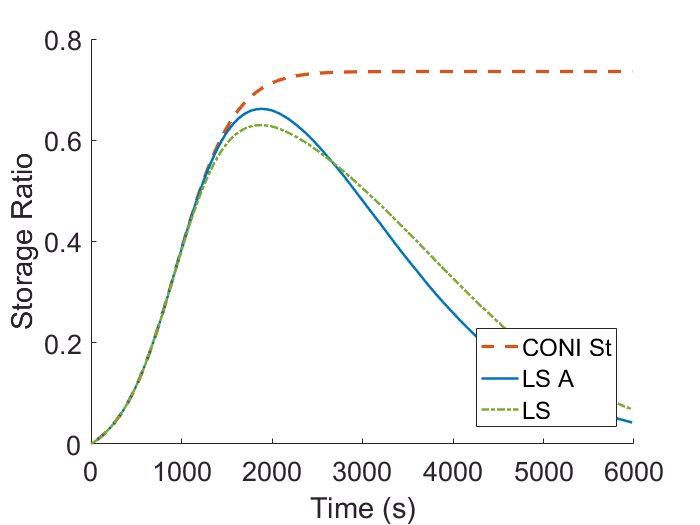


tmp2 = intBffConBinVal.* ( poisscdf(cs, cumUniConBinVal) );

plot( scale , tmp2, 'DisplayName', 'LS','LineWidth',1.5, 'LineStyle', '-.','Color', [0.47 0.67 0.19]);

%     figure; 
%     plot(scale,  tmp)
%     disp(cumUniConBinVal)

% etest2 = etest.* ( poisscdf(cs, cumUniConBinVal) )*(1-1/cs);

legend('off');
legend('show','Location','southeast');
xlabel('Time (s)');
ylabel('Storage Ratio');
set(gca,'FontSize',16); 

buff part

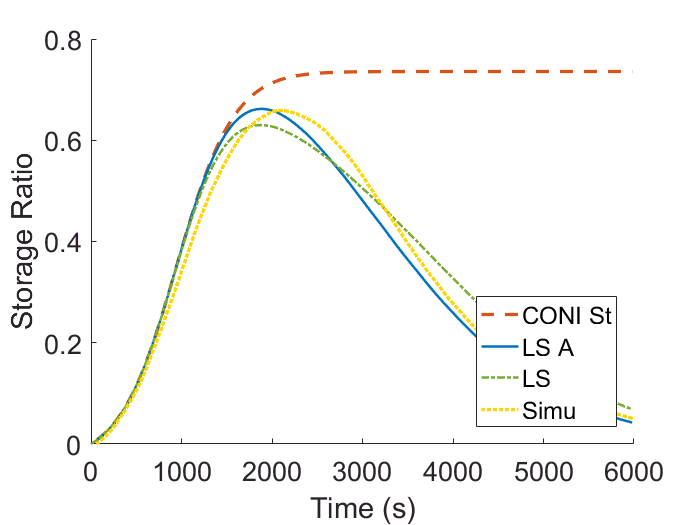

%s = 7;
con_m = content_num_process(esto,smplIntrv);
econ = con_m/(s-1);
tmax = 1:ceil(max(t)/smplIntrv);


plot( (tmax)*smplIntrv , econ(tmax), 'DisplayName', 'Simu','LineWidth',2,'LineStyle',':', 'Color', [1 0.84 0] );
legend('off');
legend('show','Location','southeast');


%get varience
inter_simu = interp1((tmax)*smplIntrv , econ(tmax) ,scale);
sumtmp = (inter_simu -intBffConBinVal).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_coni = mean( sumtmp );
disp( dist_coni );

    0.1448




sumtmp = (inter_simu -tmp).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_lsa = mean( sumtmp );
disp( dist_lsa );

   8.8156e-04




sumtmp = (inter_simu -tmp2).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_ls = mean( sumtmp );
disp( dist_ls );

    0.0013



delay part

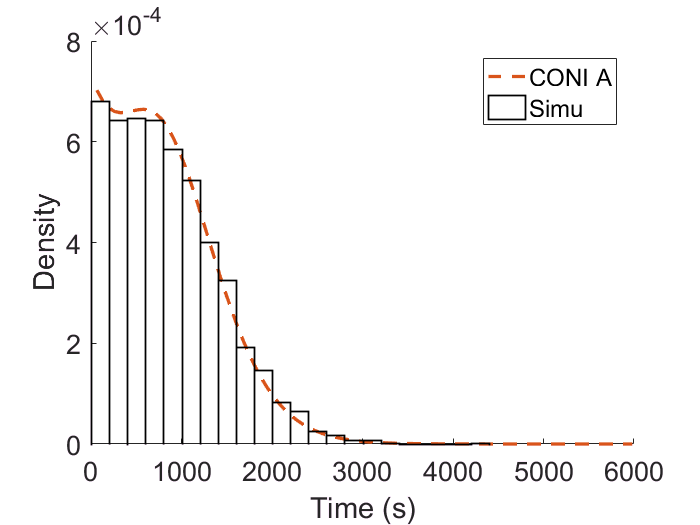


a = 1;b = 1; c = 1;  e = s*(s-1)/2;
test_size = ceil(r_l/lambda);
[trans,~] = genTransMatrix(s, a, b, c, lambda);
% buff = 10;
% r_l_r = buff*Lambda;

figure; hold on;
% delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    
% [prepdf, binVal ] = delayPDF_v3( trans, delayInit, test_size, e, lambda );
% plot((1:test_size-1)*lambda,prepdf, 'DisplayName', 'IAAP A','LineWidth',1.5,'Color', [0 0.45 0.74]); 

ini = zeros(1,size(trans,1));ini(1) = 1;
[ggpdf, binVal ] = delayPDF_v3( trans, ini, test_size, e, lambda );
% ggpdf = ggpdf ./ ggpdf( ceil(r_l_r/lambda) );
plot((1:test_size-1)*lambda, ggpdf, 'DisplayName', 'CONI A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 

ccdf = histogram(cdelay,'BinWidth',200,'Normalization','pdf','DisplayName','Simu',...
    'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
xlabel('Time (s)');
ylabel('Density');
legend('show');
set(gca,'FontSize',16)


inter_ggpdf = interp1( (1:test_size-1)*lambda , ggpdf , ccdf.BinEdges+ccdf.BinWidth/2); 
sumtmp = (inter_ggpdf(1: (size(inter_ggpdf, 2)-1) ) -ccdf.Values).^2;
sumtmp = sumtmp(~isnan(sumtmp));
dist_m = mean( sumtmp );
disp( dist_m );

   1.6243e-10



%      gain = - ggpdf + prepdf;
%      cost = - conBinVal/(s-1) + combindedBin/(s-1);
%      prftchU = gain .* (1-cost);
%      figure;
%      plot(( 1:(test_size-1) )*lambda, prftchU,'DisplayName',['R^{-1}=' num2str(Lambda)],'LineWidth',2); 
%      xlabel('Time (s)');
%     ylabel('Utility');
%     set(gca,'FontSize',16)
%  

%      gain = ggpdf;
%      cost = conBinVal/(s-1);
%      prftchU = gain .* (1-cost);
%      figure;
%      plot(( 1:(test_size-1) )*lambda, prftchU,'DisplayName',['R^{-1}=' num2str(Lambda)],'LineWidth',2); 
%      xlabel('Time (s)');
%     ylabel('Utility');
%     set(gca,'FontSize',16)
%     
%     
%     

%     %original setting is test_size = ceil(6000/lambda); and the bin width is 200
%     

truncated distribution part. modify buff to get estimated buffer constrant truncated distribution

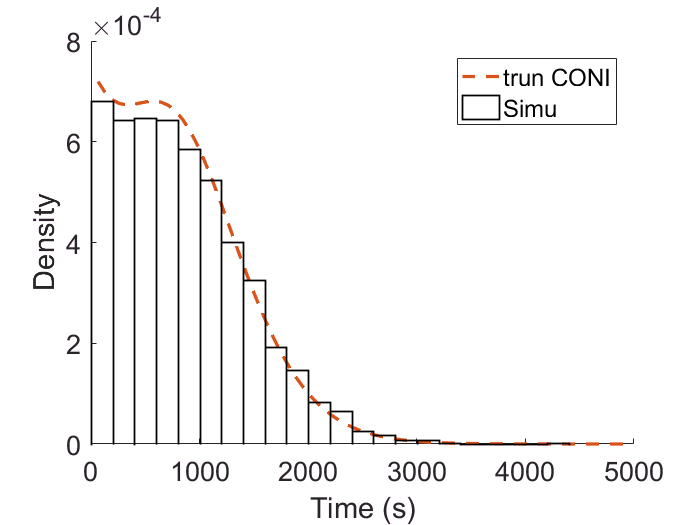

a = 1; b = 1; c = 1;  e = s*(s-1)/2; buff = 2;
% r_l_r = buff*Lambda;
r_l_r = 5000;
trun_ratio = ceil(r_l_r/lambda);
[trans,~] = genTransMatrix(s, a, b, c, lambda);



figure; hold on;
% delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    
% [prepdf, binVal ] = delayCDF_v3( trans, delayInit, test_size, e, lambda );
% plot((1:test_size-1)*lambda,prepdf, 'DisplayName', 'IAAP A','LineWidth',1.5,'Color', [0 0.45 0.74]); 

ini = zeros(1,size(trans,1)); ini(1) = 1;
[ggpdf, binVal ] = delayPDF_v3( trans, ini, trun_ratio, e, lambda );
% plot((1:trun_ratio-1)*lambda, ggpdf, 'DisplayName', 'CONI A','LineWidth',2, 'LineStyle','-','Color', [0 0.45 0.74] ); 
% ggpdf = ggpdf ./ sum(ggpdf( 1:(trun_ratio-1) ));
ggpdf = ggpdf ./ sum(ggpdf*lambda);
plot((1:trun_ratio-1)*lambda, ggpdf, 'DisplayName', 'trun CONI','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 

ccdf = histogram(cdelay,'BinWidth',200,'Normalization','pdf','DisplayName','Simu',...
    'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
xlabel('Time (s)');
ylabel('Density');
legend('show');
set(gca,'FontSize',16);

%    

fit lambda_r to current delay distribution

%     
% lambda_r = lambda;
% i = 0;
% alpha = 4;
% stdc = 0;
% stdp = 0;
% r_l_r = 6000;
% 
% for i = 1:50
%     ini = zeros(1,size(trans,1));ini(1) = 1;
%     [ggpdf, binVal ] = delayCDF_v3( trans, ini, test_size, e, lambda_r );
%     
% %     trun_ratio = ceil(r_l_r/lambda);
% %     ggpdf = ggpdf ./ ggpdf( trun_ratio-1 );
%     
%     gggpdf = [];
% 
%     
%     for j = ceil((ccdf.BinEdges+ccdf.BinWidth/2) /lambda_r)
%         if (j > size(ggpdf,2))
%             break;
%         end
%         gggpdf = [gggpdf ggpdf(j)];
%             
%     end
%     
%     array_size = min([size(ccdf.Values, 2) size(gggpdf, 2)]);
%         
%     stdc = mean( (gggpdf(1:array_size) - ccdf.Values(1:array_size) ).^2 );
% %     stdc
% %     stdp
%     if stdc >= stdp
%         alpha = alpha*-1;
%     end
%     lambda_r = lambda_r + alpha;
%     stdp = stdc;
%     
% %     gggpdf
% %     lambda_r
% end
% 
% lambda_r
% a = 1;b = 1; c = 1;  e = s*(s-1)/2;
% [trans,~] = genTransMatrix(s, a, b, c, lambda_r);
% 
% figure; hold on;
% % delayInit = combState(s, preTransSto, preInit, cont_n, conInit, indexsum, state01, trans);    
% % [prepdf, binVal ] = delayCDF_v3( trans, delayInit, test_size, e, lambda );
% % plot((1:test_size-1)*lambda,prepdf, 'DisplayName', 'IAAP A','LineWidth',1.5,'Color', [0 0.45 0.74]); 
% 
% ini = zeros(1,size(trans,1));ini(1) = 1;
% [ggpdf, binVal ] = delayCDF_v3( trans, ini, test_size, e, lambda_r );
% plot((1:test_size-1)*lambda_r, ggpdf, 'DisplayName', 'CONI A','LineWidth',2, 'LineStyle','--','Color', [0.85 0.33 0.1]); 
% 
% ccdf = histogram(cdelay,'BinWidth',100,'Normalization','cdf','DisplayName','IAAP St',...
%     'EdgeColor', 'k', 'FaceAlpha', 0, 'LineWidth',1);
% xlabel('Time (s)');
% ylabel('Density');
% legend('show');
% set(gca,'FontSize',16)